# Convolution (and upsampling)

This function implements a disrete convolution between a symbol stream and the impulse response of the TX filter (i.e., the pulse shape). To do so, the symbol stream is first upsampled in order to match the sampling rate defined by the pulse IR, and then the discrete convolution is performed).

**Inputs:**

- *symb_TX*: complex symbol stream vector of size *nb_symb x 1* where *nb_symb = *length( *symb_TX *)

- *g*: Impulse Response (IR) of the pulse of size *1 x *length( *g* )

- *sps*: number of samples per symbol 

**Ouput:**

- *signal*: result of the convolution, vector of size *[ ( nb_symb - 1 ) * sps + length( g ) ] x 1*

function signal = convolution_TX( symb_TX , g , sps )

## Upsampling

In order to match the sampling rate used to design the filter impulse response *g*, the symbol vector *symb_TX *must first be upsampled as illustrated below (zero-padding):

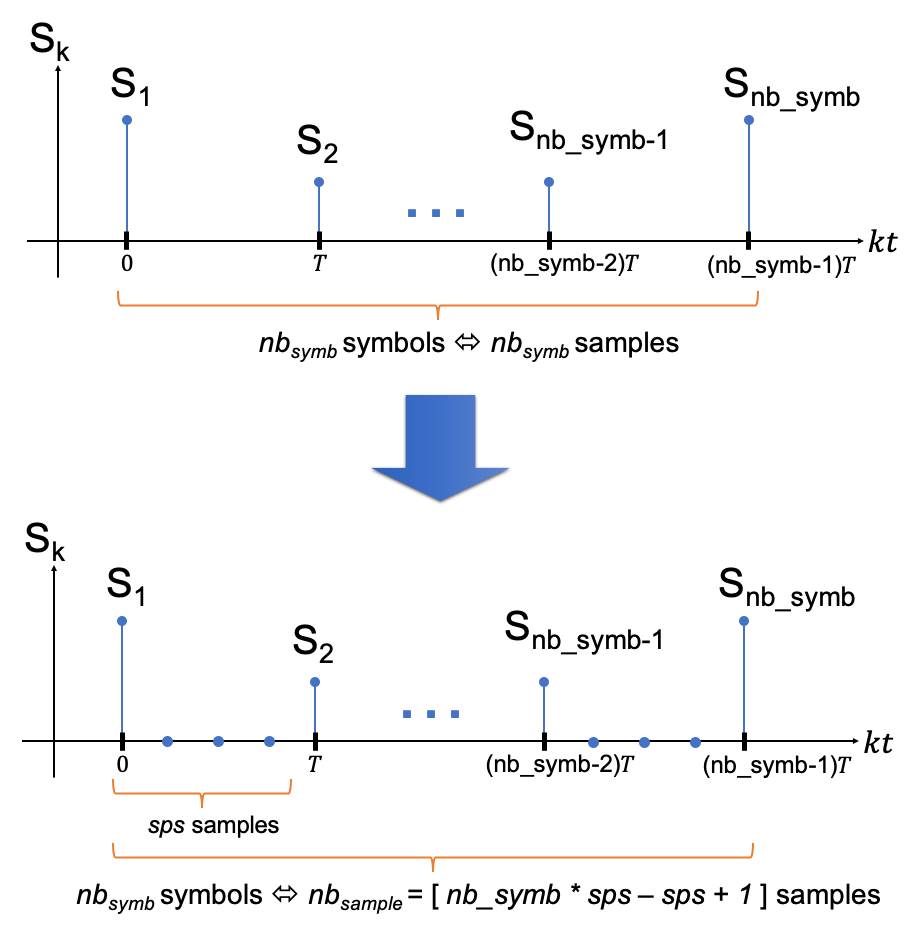

% Code the upsampling here
taille = (length(symb_TX) * sps - sps + 1);
symb_TX_upsampled = zeros(1,taille);
for i=1:length(symb_TX_upsampled)
    if mod(i-1, sps) == 0
        symb_TX_upsampled(i) = symb_TX( (  (i-1) /sps )+1  ); 
    else 
        symb_TX_upsampled(i) = 0;
    end
end


## Discrete Convolution

The discrete convolution between the upsampled symbol stream $ s_{up}$ and the filter Impulse Response (IR) $g$ is defined as $\left( s_{up} * g \right)[n]=\sum_{l=-\infty}^{+\infty}s_{up}[n-l]g[l]$. In our case, $g$ represents the filter Impulse Response (IR) which is finite (FIR filter). So the convolution can be written as a finite summation: 


$$\left( s_{up} * g \right)[n]=\sum_{l=-L}^{L}s_{up}[n-l]g[l]$$


with $n \in [1 : nb_{sample}]$ and $2L+1$ is the number of samples of the filter IR.

 To implement this finite summation in Matlab, a special care to vector indexes should be observed. Indeed, Matlab does not handle negative indexes. So the summation should be coded as:


$$\left( s_{up} * g \right)[n]=\sum_{l=-L}^{L}s_{up}[n-l]g[l+L+1]$$


An issue also raises when:

- $n\leq l$: indexes become negative in $ s_{up}$ 

- $n - l>nb_{sample}$: indexes exceed the number of elements in $ s_{up}$

 To avoid that, it is possible to fill the $ s_{up}$ vector with $2L$ zeros at the begining and $2L$ zeros at the end such as:

$ s^{filled}_{up}=[ 0~\cdots~0~s_{up}~0~\cdots~0]$. The convolution to implement becomes then:


$$\left(  s^{filled}_{up} * g \right)[n]=\sum_{l=-L}^{L} s^{filled}_{up}[n-l]g[l+L+1]$$


with $n \in [L+1 : nb_{sample}+3L]$.

% Code the discrete convolution here

% Lengths of input signal and kernel
signal_length = length(symb_TX_upsampled);
kernel_length = length(g);

% Length of the output
output_length = signal_length + kernel_length - 1;

% Initialize the output array with zeros
signal = zeros(output_length, 1);

% Perform convolution using loops
for n = 1:output_length
    for m = 1:kernel_length
        if (n - m + 1 > 0) && (n - m + 1 <= signal_length) % Check boundaries
            signal(n) = signal(n) + symb_TX_upsampled(n - m + 1) * g(m);
        end
    end
end




### Vector cropping

The vector resulting from the convolution of the filter IR and the symbol stream contains zeros at its begining and its end. They should be removed to obtain the appropriate vector size of *[ ( nb_symb - 1 ) * sps + length( g ) ] x 1*.

% Crop the resulting vector here

The size of the resulting signal, is equal to the upsampled stream PLUS the filter length - 1. There is therefore a tail at the begining and the end of the time domain vector introduced by the filter delay.

end